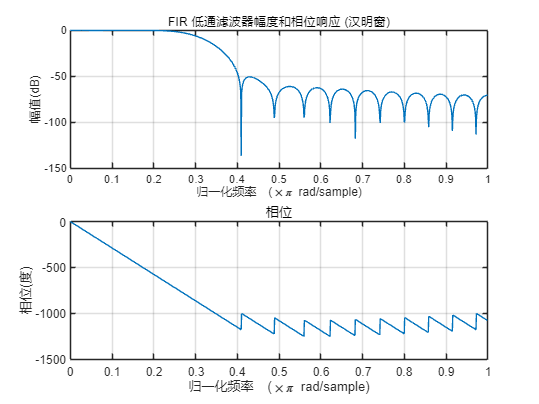

% 设计参数
wp = 0.2 * pi;       % 通带截止频率 (绿色注释：归一化频率，范围 0 到 π)
ws = 0.4 * pi;       % 阻带截止频率 (绿色注释：归一化频率)
As = 45;             % 阻带衰减 (dB) (绿色注释：汉明窗满足此要求)

% 选择汉明窗 (Hamming) (绿色注释：窗函数类型根据阻带衰减选择)
wc = (wp + ws) / 2;  % 截止频率 (绿色注释：取通带和阻带的中间值)
delta_w = ws - wp;   % 过渡带宽 (绿色注释：用于计算滤波器长度)

% 计算滤波器长度 N (绿色注释：汉明窗的过渡带公式 N ≈ 6.6π/Δω)
N = ceil(6.6 * pi / delta_w);  
if mod(N, 2) == 0
    N = N + 1;       % 确保 N 是奇数 (绿色注释：线性相位要求奇数长度)
end

% 设计 FIR 滤波器 (绿色注释：fir1 函数生成滤波器系数)
h = fir1(N-1, wc/pi, 'low', hamming(N));

% 绘制频率响应 (绿色注释：默认绘制幅度和相位)
freqz(h, 1, 1024);
title('FIR 低通滤波器幅度和相位响应 (汉明窗)');

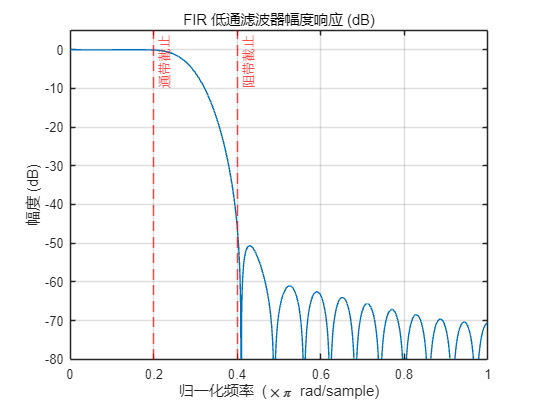


% 绘制幅度响应 (dB) (绿色注释：单独绘制对数幅度)
figure;
[H, w] = freqz(h, 1, 1024);
plot(w/pi, 20*log10(abs(H)));
grid on;
xlabel('归一化频率 (\times\pi rad/sample)');
ylabel('幅度 (dB)');
title('FIR 低通滤波器幅度响应 (dB)');
xline(wp/pi, '--r', '通带截止');  % 绿色注释：标记通带边界
xline(ws/pi, '--r', '阻带截止');  % 绿色注释：标记阻带边界
ylim([-80, 5]);                   % 绿色注释：设置纵轴范围

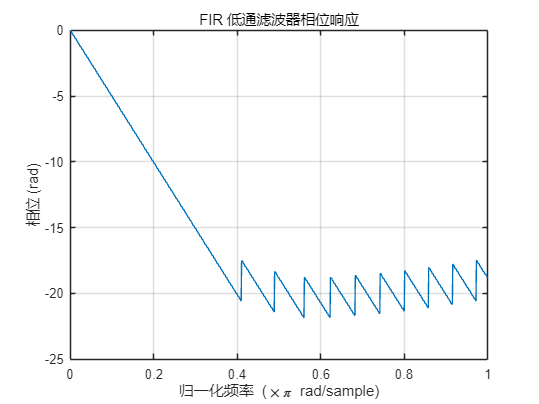


% 绘制相位响应 (绿色注释：展开相位避免跳变)
figure;
plot(w/pi, unwrap(angle(H)));
grid on;
xlabel('归一化频率 (\times\pi rad/sample)');
ylabel('相位 (rad)');
title('FIR 低通滤波器相位响应');